Short Project - Marc Obiols y Cristian Roa

close all
clear

%Cargar cuerpo
load('F_V_Human_Body.mat')
load('F_V_N_Skull.mat')
%Trasladar cuerpo

v_h=[V';ones(1,24461)]

v_h =    -1.3143   -1.4575   -1.3688   -1.2726   -1.3174   -1.2444   -1.4216   -1.3357   -1.4552   -1.3563   -1.4795   -1.3765   -1.2430   -1.2527   -1.1413   -1.2678   -1.1531   -1.2865   -1.1706   -1.3089   -1.1937   -1.3359   -1.2229   -1.0730   -1.0497   -1.1032   -1.4398   -1.4683   -1.3694   -1.4170   -1.2595   -1.3964   -1.4989   -1.5151   -1.0328   -1.0225   -0.8960   -1.0193   -0.8990   -1.1364   -1.0240   -1.1414   -0.9002   -0.9088   -0.7844   -0.7755   -0.7727   -1.1592   -1.0540   -1.1837
   15.0686   15.1137   15.2156   15.1795   15.2749   15.2717   15.2928   15.3383   15.3808   15.4239   15.4726   15.5177   15.3610   15.4569   15.4855   15.5576   15.5951   15.6606   15.7067   15.7632   15.8188   15.8628   15.9295   15.8763   15.7536   15.9986   15.7992   15.8806   15.9569   15.7091   16.0366   15.6140   15.5654   15.6564   15.6323   15.5130   15.4126   15.3957   15.5393   15.3785   15.2784   15.2729   15.2863   15.6680   15.6998   15.5626   15.4280   15.1638   15.0343   

V = transl(0,0,2)*v_h;
V = V'

V =    -1.3143   15.0686    0.3542    1.0000
   -1.4575   15.1137    0.4084    1.0000
   -1.3688   15.2156    0.3331    1.0000
   -1.2726   15.1795    0.3052    1.0000
   -1.3174   15.2749    0.2946    1.0000
   -1.2444   15.2717    0.2713    1.0000
   -1.4216   15.2928    0.3312    1.0000
   -1.3357   15.3383    0.2857    1.0000
   -1.4552   15.3808    0.3190    1.0000
   -1.3563   15.4239    0.2734    1.0000


V = V(:,1:3)

V =    -1.3143   15.0686    0.3542
   -1.4575   15.1137    0.4084
   -1.3688   15.2156    0.3331
   -1.2726   15.1795    0.3052
   -1.3174   15.2749    0.2946
   -1.2444   15.2717    0.2713
   -1.4216   15.2928    0.3312
   -1.3357   15.3383    0.2857
   -1.4552   15.3808    0.3190
   -1.3563   15.4239    0.2734


Box_max=max(V)

Box_max =     5.8425   20.6841    3.9170


Box_min=min(V)

Box_min =    -5.8425   -0.0566    0.1469


Box=Box_max-Box_min

Box =    11.6850   20.7407    3.7701



%Dibujar cuerpo
hold on
patch('Faces', F, 'Vertices', V,...
      'FaceColor',[0.8 0.8 1.0],...
      'EdgeColor','none',...
      'FaceLighting',    'gouraud',     ...
      'AmbientStrength', 0.8,'FaceAlpha', 0.6);
camlight('headlight');
material('dull');

axis equal
view(45,45)
xlabel 'X'; ylabel 'Y'; zlabel 'Z'

%Dibujar mesa
Mesa_V= [-7 0 0;7 0 0;-7 20 0;7 20 0]

Mesa_V =     -7     0     0
     7     0     0
    -7    20     0
     7    20     0


Mesa_F = [1 2 4 3 ]

Mesa_F =      1     2     4     3


hold on
patch('Vertices',Mesa_V,'Faces',Mesa_F,'FaceVertexCData',hsv(1),'FaceColor','flat')

%Pintar craneo
Ve = Ve*0.1

Ve =    -0.1646   -1.4796    0.1098
   -0.1255   -1.4964    0.1068
   -0.1220   -1.4897    0.1431
   -0.1607   -1.4737    0.1450
   -0.0848   -1.5101    0.1036
   -0.0822   -1.5029    0.1403
   -0.0797   -1.4935    0.1816
   -0.1190   -1.4811    0.1842
   -0.1576   -1.4659    0.1851
   -0.0427   -1.5196    0.1010



Ve_h=[Ve';ones(1,40062)]

Ve_h =    -0.1646   -0.1255   -0.1220   -0.1607   -0.0848   -0.0822   -0.0797   -0.1190   -0.1576   -0.0427   -0.0414   -0.0000   -0.0000         0   -0.0399   -0.0388   -0.0779         0         0   -0.0381   -0.0771   -0.1179   -0.1574   -0.1176   -0.1643   -0.4629   -0.4555   -0.4620   -0.4699   -0.4478   -0.4541   -0.4614   -0.4695   -0.4778   -0.4369   -0.4438   -0.4236   -0.4312   -0.4389   -0.4513   -0.4585   -0.4689   -0.4459   -0.4530   -0.4657   -0.4767   -0.4775   -0.4863   -0.4859   -0.4952
   -1.4796   -1.4964   -1.4897   -1.4737   -1.5101   -1.5029   -1.4935   -1.4811   -1.4659   -1.5196   -1.5121   -1.5233   -1.5157   -1.5054   -1.5021   -1.4929   -1.4850   -1.4958   -1.4888   -1.4864   -1.4794   -1.4729   -1.4581   -1.4681   -1.4498   -1.0730   -1.0730   -1.0450   -1.0454   -1.0731   -1.0450   -1.0178   -1.0179   -1.0186   -1.0716   -1.0437   -1.0687   -1.0413   -1.0142   -1.0166   -0.9897   -0.9913   -0.9871   -0.9608   -0.9637   -0.9658   -0.9918   -0.9928   -0.9671  

Ve= transl(0,18,2)*trotx(-pi/2)*Ve_h;
Ve = Ve'

Ve =    -0.1646   18.1098    3.4796    1.0000
   -0.1255   18.1068    3.4964    1.0000
   -0.1220   18.1431    3.4897    1.0000
   -0.1607   18.1451    3.4737    1.0000
   -0.0848   18.1036    3.5101    1.0000
   -0.0822   18.1403    3.5029    1.0000
   -0.0797   18.1816    3.4935    1.0000
   -0.1190   18.1842    3.4811    1.0000
   -0.1576   18.1851    3.4659    1.0000
   -0.0427   18.1010    3.5196    1.0000


Ve = Ve(:,1:3)

Ve =    -0.1646   18.1098    3.4796
   -0.1255   18.1068    3.4964
   -0.1220   18.1431    3.4897
   -0.1607   18.1451    3.4737
   -0.0848   18.1036    3.5101
   -0.0822   18.1403    3.5029
   -0.0797   18.1816    3.4935
   -0.1190   18.1842    3.4811
   -0.1576   18.1851    3.4659
   -0.0427   18.1010    3.5196


hold on
patch('Faces', Fa, 'Vertices', Ve,...
      'FaceColor',[0.2 0.2 0.2],...
      'EdgeColor','none',...
      'FaceLighting',    'gouraud',     ...
      'AmbientStrength', 0.8,'FaceAlpha', 0.6);
camlight('headlight');
material('dull');

%Mesa auxiliar
%Dibujar mesa
Mesa_V= [10 10 0;15 10 0;10 20 0;15 20 0]

Mesa_V =     10    10     0
    15    10     0
    10    20     0
    15    20     0


Mesa_F = [1 2 4 3 ]

Mesa_F =      1     2     4     3


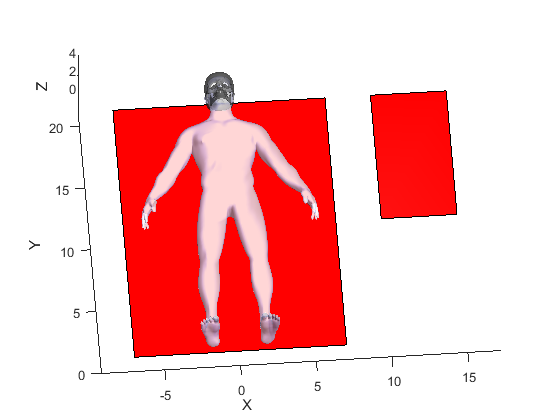

hold on
patch('Vertices',Mesa_V,'Faces',Mesa_F,'FaceVertexCData',hsv(1),'FaceColor','flat')